# ******************************************************************************

# DYNAMIC RESPONSE DUE TO EARTHQUAKE LOADING USING

# WILSON RECURRENCE FORMULA

# ******************************************************************************

#### *Code established by : **Dr. Raouf Bencharif  * 

#### *                                      e-mail : *[rbencharif@cgsdz.org](http://rbencharif@cgsdz.org)

#### *                                     Researchgate : *[https://www.researchgate.net/profile/Raouf-Bencharif](https://www.researchgate.net/profile/Raouf-Bencharif)

####                                      Google Scholar : [https://scholar.google.com/citations?user=2ps9VqIAAAAJ](https://scholar.google.com/citations?user=2ps9VqIAAAAJ)

#### *Senior Researcher, at the National Center of Applied Research in Earthquake Engineering,CGS, (*[http://www.cgs-dz.org/index.php/fr/](http://www.cgs-dz.org/index.php/fr/))              

#### *Department of structural Dynamic Testing, *[http://www.cgs-dz.org/index.php/fr/laboratoires/un-laboratoire-d-essais-dynamiques-des-structures](http://www.cgs-dz.org/index.php/fr/laboratoires/un-laboratoire-d-essais-dynamiques-des-structures)              

## 1. Introduction

Figure 1.1 shows a SDOF system, with viscous damping and external forcing in schematic form. The mass $m$, is assumed to be excited directly by an external force, $p\left(t\right)$. The system will be assumed to be in equilibrium when the applied force is zero; any compression or extrusion of the spring due to gravity, for example, is assumed to have already taken plan, and can be ignored as far as the vibration response is concerned.

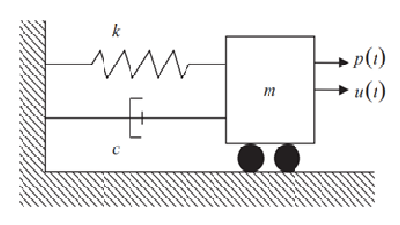

**Figure 1.1: SDOF System with Force Input**

The equation of motion governing the relative displacement  $u\left(t\right)$ of the linearly elastic structure is given by

                                                                                                                $m\ddot{u} +c\dot{u} +ku=p\left(t\right)$ or $m\ddot{u} +2\rho m\omega_n \dot{\;u} +ku=p\left(t\right)$

In the code, **WILSON RECURRENCE FORMULA** is employed for the numerical integration of the above equation. This method is versatile as it can handle irregular loading patterns, such as earthquake ground motion, and accommodate structures whose members transition from elastic to inelastic during response.

## 2. Numerical Implementation of the "**WILSON RECURRENCE FORMULA"**

Pseudo-Code of the Central Difference Method (Chopra, 2011)

               
$$u_{i+1} =au_i +b\dot{u} +cp_i +dp_{i+1}$$


               
$$\dot{u} =a^{\prime } u_i +b^{\prime } \dot{u} +c^{\prime } p+d^{\prime } p_{i+1}$$


These equations are the recurrence formulae for the coefficients given below depend on $\omega_n$, $k$ and $\rho$ and time interval . In practice  should be sufficiently small to closely approximate the excitation force and also to render results at the required time intervals. The practice to select   where T is the natural period of the structure. This is to ensure that the important peaks of structural response are not omitted. As long as  is constant, the recurrence formulae coefficients need to be calculated once.

               
$$a=e^{-\rho \omega_n \Delta t} \left(\rho \mathrm{\ }\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{\ }\omega_d \Delta t+\sqrt{1-\rho^2 }\mathrm{\ }\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{\ }\omega_d \Delta t\right)/\sqrt{1-\rho^2 }$$


               
$$b=e^{-\rho \omega_n \Delta t} \left(\frac{1}{\omega_d }sin{\ \omega }_d \Delta t\right)$$


               
$$c=\frac{1}{k\omega_n \Delta t}{\left\{2\rho +e^{-\rho \omega_n \Delta t} \omega_n \Delta t{\left[{\left(\frac{1-2\rho^2 }{\omega_d \Delta t}-\frac{p}{\sqrt{1-\rho^2 }}\right)}sin{\ \omega }_d \Delta t-{\left(1+\frac{2\rho }{{\ \omega }_d \Delta t}\right)}\mathrm{\ }\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{\ }\omega_d \Delta t\right]}\right\}}$$


               
$$d=\frac{1}{k\omega_n \Delta t}{\left\{\omega_n \Delta t-2\rho +e^{-\rho \omega_n \Delta t} \omega_n \Delta t{\left[{\left(\frac{2\rho^2 -1}{\omega_d \Delta t}\right)}\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{\ }\omega_d \Delta t+{\left(\frac{2\rho }{\omega_n \Delta t}\right)}\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{\ }\omega_d \Delta t\right]}\right\}}$$


                
$$a^{\prime } =-e^{\rho \omega_n \Delta t} {\left(\frac{\omega_n }{\sqrt{1-\rho^2 }}\mathrm{\ }\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{\ }\omega_d \Delta t\right)}$$


                
$$b^{\prime } =e^{-\rho \omega_n \Delta t} {\left(-\rho sin\omega_d \Delta t+\sqrt{1-\rho^2 }\mathrm{\ }\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{\ }\omega_d \Delta t\right)}/\sqrt{1-\rho^2 }$$


                
$$c^{\prime } =\frac{1}{k\Delta t}{\left\{-1+e^{-\rho \omega_n \Delta t} {\left[{\left(\frac{\omega_n \Delta t}{\sqrt{1-\rho^2 }}+\frac{\rho }{\sqrt{1-\rho^2 }}\right)}sin{\ \omega }_d \Delta t+\mathrm{\ }\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{\ }\omega_d \Delta t\right]}\right\}}$$


                
$$d^{\prime } =\frac{1}{k\Delta t}{\left\{1-e^{-\rho \omega_n \Delta t} {\left[\frac{\rho }{\sqrt{1-\rho^2 }}sin{\ \omega }_d \Delta t+\mathrm{\ }\mathrm{c}\mathrm{o}\mathrm{s}\mathrm{\ }{\ \omega }_d \Delta t\right]}\right\}}$$


If the excitation is ground acceleration ${\ddot{u} }_g \left(t\right)$replace $p_i$ by ${-m\;\ddot{u} }_{\textrm{gi}}$ where in this case ui, ˙ui,and ¨ui give response values relative to the ground.

The computed $u_i$, ${\dot{u} }_i$ , and ${\ddot{u} }_i$ give response values relative to the ground. If needed, the total velocity and acceleration can be computed readily: ${\dot{u} }_i^t ={\dot{u} }_i +{\dot{u} }_{gi}$ and ${\ddot{u} }_i^t ={\ddot{u} }_i +{\ddot{u} }_{gi}$

The central difference method will “blow up,” giving meaningless results, in the presence of numerical round-off if the time step chosen is not short enough. The specific requirement for stability is

                                                                                                                
$$\Delta t<\frac{T}{10}$$


## *3. Reference *

Chopra, Anil K. (2011), Dynamics Structures: Theory and Applications to Earthquake Engineering, 4th Edition, Prentice Hall, New Jersey.

Rajasekaran, S. (2009). *Structural dynamics of earthquake engineering: theory and application using MATHEMATICA and MATLAB*. Elsevier.

RAY, W. Clough et JOSEPH, Penzien (2003). Dynamics of structures. *Computers & Structures, Berkeley, CA, USA*.

## 3. Input motion

clear all;clc;
load KOBE.txt                % Accelerqtion time history 
g=9.8;                       % Gravity                    [m/s²]
t=KOBE(:,1);                 % Time                       [s]
Ag=KOBE(:,2)*g;              % Acceleration               [m/s²]       
dt= t(2)-t(1);               % Time interval              [s]
At=KOBE;

## 4. Plot input motion

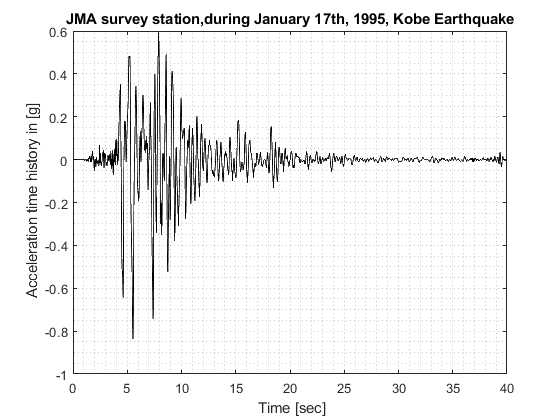

plot(t,Ag/g,'k');xlabel(' Time [sec]');
              ylabel(' Acceleration time history in [g]');
              title('JMA survey station,during January 17th, 1995, Kobe Earthquake');grid minor;

## 5. Characteristics of the SDOF system

m=120;                       % Mass                      [Ton]
T=0.4;                       % Period                    [seconds]
k=m*(2*pi/T)^2;              % Stiffness                 [KN]
zeta =0.05;                  % Critical damping Ratio    [%]
wn=sqrt(k/m);                % Circular frequency        [rad/s]
C=2*m*wn*zeta;               % Damping value             [KN s/m]


## 6. Vector force  

P=-m*Ag;                      % Load vector              [KN]

## 7. Check of stability condition

if dt<T/10
    display('The solution is stable')
else
    display('The solution is not stable')
end

The solution is stable


## 8. Initial calculations

u(1)=0;
v(1)=0;

## 9. Calculation process

wd=wn*sqrt(1-zeta^2);

a=exp(-zeta*wn*dt)*(zeta*sin(wd*dt)/sqrt(1-zeta^2)+cos(wd*dt));
b=exp(-zeta*wn*dt)*(sin(wd*dt))/wd;
c2=((1-2*zeta^2)/(wd*dt)-zeta/sqrt(1-zeta^2))*sin(wd*dt)-(1+2*zeta/(wn*dt))*cos(wd*dt);
c=(1/k)*(2*zeta/(wn*dt)+exp(-zeta*wn*dt)*(c2));
d2=exp(-zeta*wn*dt)*((2.0*zeta^2-1)/(wd*dt)*sin(wd.*dt)+2.0*zeta/(wn*dt)*cos(wd*dt));
d=(1/k)*(1-2.0*zeta/(wn*dt)+d2);

ad=-exp(-zeta*wn*dt)*wn*sin(wd*dt)/(sqrt(1-zeta^2));
bd=exp(-zeta*wn*dt)*(cos(wd*dt)-zeta*sin(wd*dt)/sqrt(1-zeta^2));
c1 = exp(-zeta*wn*dt)*((wn/sqrt(1-zeta^2)+zeta/(dt*sqrt(1-zeta^2)))*sin(wd*dt)+cos(wd*dt)/dt);
cd=(1/k)*(-1/dt+c1);
d1=exp(-zeta*wn*dt)*(zeta*sin(wd*dt)/sqrt(1-zeta^2)+cos(wd*dt));
dd=(1/(k*dt))*(1-d1);

for i=2:length(P)
    u(i)=a*u(i-1)+b*v(i-1)+c*P(i-1)+d*P(i);
    v(i)=ad*u(i-1)+bd*v(i-1)+cd*P(i-1)+dd*P(i);
end

## 10. Plot responses

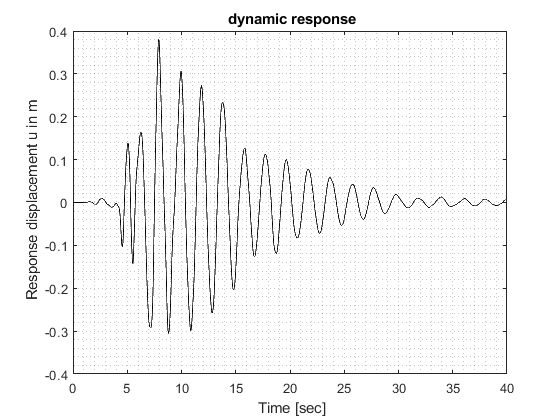



plot(t,u,'k');xlabel(' Time [sec]');
              ylabel(' Response displacement u in m');
              title(' dynamic response');grid minor;

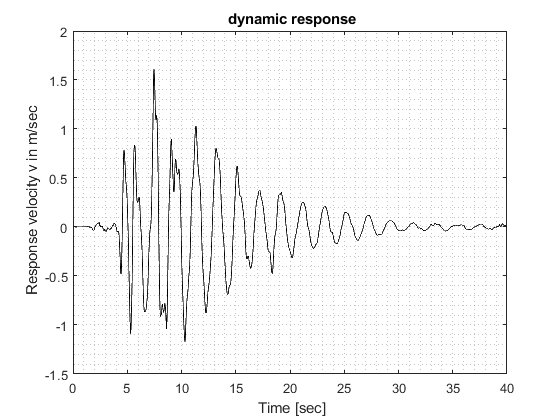


plot(t,v,'k');xlabel(' Time [sec]');
              ylabel(' Response velocity v in m/sec');
              title(' dynamic response');grid minor;